## **Geological Model**

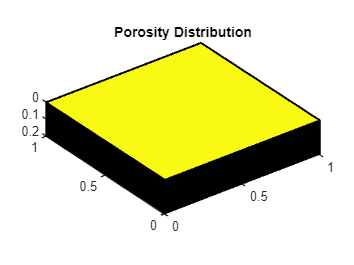

% Define grid dimensions
Nx = 1; % Number of grid cells in x-direction
Ny = 1; % Number of grid cells in y-direction
Nz = 100; % Number of grid cells in z-direction
Lx = 1; % Length of the reservoir in x-direction (meters)
Ly = 1; % Length of the reservoir in y-direction (meters)
Lz = 0.2; % Length of the reservoir in z-direction (meters)

% Create Cartesian grid
G = cartGrid([Nx, Ny, Nz], [Lx, Ly, Lz]);
G=computeGeometry(G);

% Define petrophysical properties
poro = 0.3; % Porosity
perm = 0.02e-12; % Permeability (m^2)
rock.perm = perm * ones(Nz, 1); % Assume homogeneous permeability
rock.poro = poro * ones(Nz, 1); % Assume homogeneous porosity

% Visualize the grid
plotCellData(G, rock.poro);
view(3), axis equal tight, title('Porosity Distribution');

## Flow Model

% Define fluid properties
mu_w = 0.001; % Water viscosity (Pa.s)
mu_o = 0.001; % Oil viscosity (Pa.s)
rho_w = 1000; % Water density (kg/m^3)
rho_o = 660; % Oil density (kg/m^3)
D = 5.6e-8; % Diffusion coefficient for nanoparticles (m^2/s)
gamma_d = 16; % Rate coefficient for surface retention of nanoparticles (1/m)
gamma_pt = 1.28; % Pore throat blocking constant (1/m)
gamma_e = 30; % Rate coefficient for entrainment of nanoparticles (1/m)
u_c = 4.6e-6; % Critical velocity for nanoparticles deposition (m/s)
c_0 = 0.004; % Initial concentration of nanoparticles (m^3/m^3)
H = 0.2; % Rock depth (m)
S_wr = 0.001; % Irreducible water saturation
S_or = 0.001; % Residual oil saturation
a_w = 0.5; % Pore size distribution index for imbibition
a_o = 0.5; % Pore size distribution index for drainage
b_w = 500; % Constant for entry pressure for imbibition
b_o = -500; % Constant for entry pressure for drainage
phi_0 = 0.3; % Initial porosity
l = 3; % Exponent in permeability variation equation
k_f = 0.6; % Constant for fluid seepage allowed by the plugged pores
gamma_f = 0.01; % Coefficient of flow efficiency for nanoparticles
k_rw_0 = 1; % Endpoint relative permeability of water phase
k_ro_0 = 1; % Endpoint relative permeability of oil phase
a = 4; % Constant in relative permeability relation
b = 4; % Constant in relative permeability relation
K_0 = 0.02e-12; % Initial absolute permeability (m^2)
S_w_0 = 0.27; % Initial water saturation
S_o_0 = 0.73; % Initial oil saturation
g = 9.81; % Gravitational acceleration (m/s^2)

% Define initial and boundary conditions
bc = 'neu'; % Neumann boundary condition
p0 = 0; % Reference pressure (Pa)

% Define time parameters
t_inf = 100; % Total simulation time (s)
dt = 1e-3; % Initial time step (s)

## **Descretize and Run the Simulation**

% Define simulation parameters
num_steps = ceil(t_inf / dt); % Total number of time steps
dt_vec = repmat(dt, num_steps, 1); % Time step vector

% Initialize arrays to store results
S_w_history = nan(num_steps, G.cells.num);
S_history = nan(num_steps,G.cells.num);
c_history = nan(num_steps, G.cells.num);
c_s1_history = nan(num_steps, G.cells.num);
c_s2_history = nan(num_steps, G.cells.num);

% Define initial values
S_w = S_w_0 * ones(G.cells.num, 1);
S = (S_w-S_w_0) / (1-S_o_0-S_w_0);
c = zeros(G.cells.num, 1);
c_s1 = zeros(G.cells.num, 1);
c_s2 = zeros(G.cells.num, 1);

% Calculate initial values of k_rw, k_ro, p_c based on S_w and c
k_rw = k_rw_0 * S.^a;
k_ro = k_ro_0 * (1 - S).^b;
p_c = b_w * (S + eps(1)).^(-a_w) + b_o * (1 - S + eps(1)).^(-a_o); 
u_w = 0;
% Main simulation loop
for i = 1:num_steps
    % Calculate other variables using provided equations
    % Calculate mobility ratios
    lambda_w = k_rw / mu_w;
    lambda_o = k_ro / mu_o;
    lambda_t = lambda_w + lambda_o;
    
    % Calculate flow fractions
    f_w = lambda_w ./ lambda_t;
    f_o = lambda_o ./ lambda_t;

    % Solve the system of equations for S_w, c, c_s1, and c_s2
    [S_w, c, c_s1, c_s2] = solve_system_of_equations(S_w, S, c, c_s1, c_s2, k_rw, k_ro, p_c, u_w)
    
    % Store results in history arrays
    S_w_history(i, :) = S_w';
    c_history(i, :) = c';
    c_s1_history(i, :) = c_s1';
    c_s2_history(i, :) = c_s2';
    
    % Update values of the variables (phi, K, k_rw, k_ro, p_c, u_w)
    [phi, K, k_rw, k_ro, p_c, u_w] = update_values(S_w, c, c_s1, c_s2, phi, K, k_rw, k_ro, p_c, u_w)

    % Update time step
    dt = dt_vec(i);
end

## **Plot the Results**

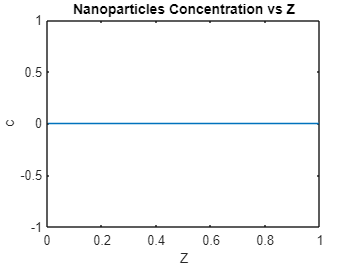

% Set Z = z / H
Z = G.cells.centroids(:, 3) / H;

% Plot c vs Z
figure;
plot(Z, c_history(end, :));
xlabel('Z');
ylabel('c');
title('Nanoparticles Concentration vs Z');

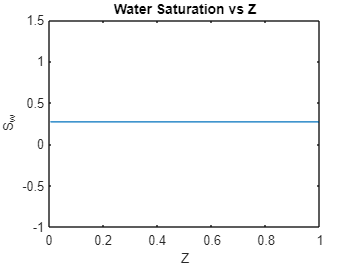


% Plot S_w vs Z
figure;
plot(Z, S_w_history(end, :));
xlabel('Z');
ylabel('S_w');
title('Water Saturation vs Z');

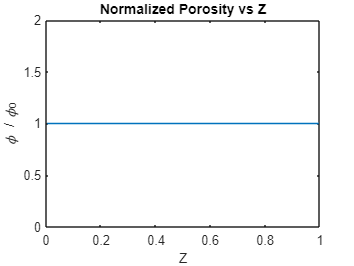


% Plot phi / phi_0 vs Z
phi = phi_0 - (c_s1_history(end, :) + c_s2_history(end, :));
figure;
plot(Z, phi ./ phi_0);
xlabel('Z');
ylabel('\phi / \phi_0');
title('Normalized Porosity vs Z');

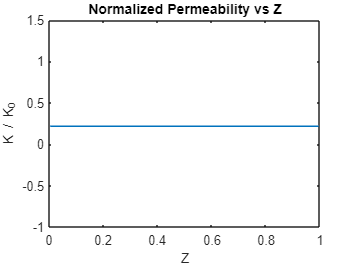


% Plot K / K_0 vs Z
K = K_0 * ((1 - gamma_f * c_s2_history(end, :)) * k_f + gamma_f * c_s2_history(end, :) .* phi ./ phi_0) .^ l;
figure;
plot(Z, K ./ K_0);
xlabel('Z');
ylabel('K / K_0');
title('Normalized Permeability vs Z');

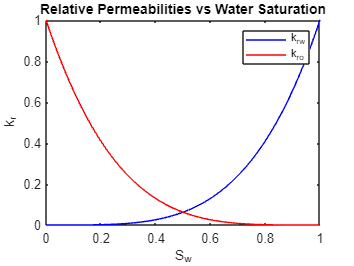


% Plot k_rw, k_ro vs S_w
S_w_range = linspace(0, 1, 100);
k_rw = k_rw_0 * S_w_range.^a;
k_ro = k_ro_0 * (1 - S_w_range).^b;
figure;
plot(S_w_range, k_rw, 'b', S_w_range, k_ro, 'r');
xlabel('S_w');
ylabel('k_r');
title('Relative Permeabilities vs Water Saturation');
legend('k_{rw}', 'k_{ro}');

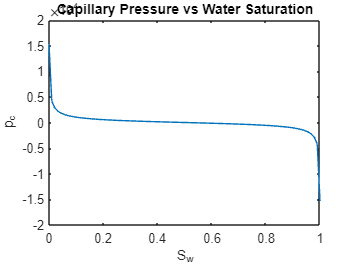


% Plot p_c vs S_w
S_w_range = linspace(0, 1, 100);
p_c = b_w * (S_w_range + eps(1)).^(-a_w) + b_o * (1 - S_w_range + eps(1)).^(-a_o);
figure;
plot(S_w_range, p_c);
xlabel('S_w');
ylabel('p_c');
title('Capillary Pressure vs Water Saturation');